## B Running HPC for LDE, then test LIF only

## 1. Setting up network

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

FigurePath = [CurrentFolder '/Figures/Demo022722/'];
addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/SIEMt0.118_SEIMt2.028/']; % V1
%SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/']; % V1
addpath(SaveFolder)
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/16Function_Scheme/']; % V1
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2';
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))
%load("AllMFPixPara_Paper2TuneFig1V4D2.mat")
%load("AllMFPixPara_Paper2TuneFig1V5D1.mat")
%load("AllMFPixPara_Paper2Tune.mat")
close all

if MF+v: omitting

If LIF-only: see coverage. Omitting

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
AngCtgr = 1; AngPrint = AngleList{AngCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5
L6up = 60; L6low = 6;
%load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc1_L6c1.mat',AngPrint))

load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc1_L6c1_L6_%d_%d_Cosine_All.mat',...
     DataPoint,AngPrint,L6up,L6low))
a1 = length(unique(L4ERcrd)); a2 = floor(length(L4ERcrd)/a1);
rowsmWin = 30; colswWin = 5;
MFv = false;
smth = true;
if MFv 
    LIFN = 5;
else
    LIFN = 3;
end

Load and make all 16 functions for this angle

LGNlist = 4; L6list = 4;
LDEFrVecS = zeros(length(L4ERcrd),LGNlist,L6list);
LDEFrVecC = zeros(length(L4ERcrd),LGNlist,L6list);
LDEFrVecI = zeros(length(L4ERcrd),LGNlist,L6list);
ContourInfoAll = cell(3,LGNlist,L6list); % Use this for E-I relation

plotFlag = true;
%CtgrName = {'func1','func2','func3','func4','func5','func6','func7'};
for LGNCtgr = 1:LGNlist
    figure(LGNCtgr)
    for L6Ctgr = 1:L6list  
        %Ctgr = [LGNCtgr,L6Ctgr];
        %load(sprintf('Paper2_LIFoLDE_Fig1V4D1_Ang%s_LGNc%d_L6c%d.mat',...
        %                                           AngPrint,LGNCtgr,L6Ctgr))
        if exist(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All.mat',...
                      DataPoint,AngPrint,LGNCtgr,L6Ctgr,L6up,L6low)) > 0
        load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All.mat',...
                      DataPoint,AngPrint,LGNCtgr,L6Ctgr,L6up,L6low))
        else %% 22.5: (1 4) (2 3) switchable
            disp("Warning! File non exists, using replacement...")
            switch L6Ctgr
                case 1
                    load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All.mat',...
                      DataPoint,AngPrint,LGNCtgr,4,L6up,L6low))
                case 2
                    load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All.mat',...
                      DataPoint,AngPrint,LGNCtgr,3,L6up,L6low))
                case 3
                    load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All.mat',...
                        DataPoint,AngPrint,LGNCtgr,2,L6up,L6low))
                case 4
                    load(sprintf('Paper2_LIFoLDE_Fig1%s_Ang%s_LGNc%d_L6c%d_L6_%d_%d_Cosine_All.mat',...
                        DataPoint,AngPrint,LGNCtgr,1,L6up,L6low))
            end
        end
        L4EPlot = reshape(L4ERcrd,a2,a1);
        L4IPlot = reshape(L4IRcrd,a2,a1);
        FrLDE = zeros(length(f_EnIOut),LIFN);
        for LDEInd = 1:length(f_EnIOut)
            if ~(isempty(f_EnIOut{LDEInd}) || size(f_EnIOut{LDEInd},2)<25)
                FrLDE(LDEInd,:) = (mean(f_EnIOut{LDEInd}(:,floor(end/2):end),2))';
            else
                FrLDE(LDEInd,:) = nan;
            end
        end
        FrLDE(FrLDE<0) = eps;
        % S rates
        subplot(L6list,3,(L6Ctgr-1)*3+1)
        [LDEFrVecS(:,LGNCtgr,L6Ctgr), ContourInfoAll{1,LGNCtgr,L6Ctgr}]= ...
            LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
            LGNCtgr,L6Ctgr,'S',smth,plotFlag,MFv, [rowsmWin, colswWin] );
        
        % C rates
        subplot(L6list,3,(L6Ctgr-1)*3+2)
        [LDEFrVecC(:,LGNCtgr,L6Ctgr), ContourInfoAll{2,LGNCtgr,L6Ctgr}] = ...
            LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
            LGNCtgr,L6Ctgr,'C',smth,plotFlag,MFv, [rowsmWin, colswWin] );
        
        % I rates
        subplot(L6list,3,(L6Ctgr-1)*3+3)
        [LDEFrVecI(:,LGNCtgr,L6Ctgr), ContourInfoAll{3,LGNCtgr,L6Ctgr}] = ...
            LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,...
            LGNCtgr,L6Ctgr,'I',smth,plotFlag,MFv, [rowsmWin, colswWin] );
    end
end
close all

Create a function

L4EfuncX = linspace(min(L4ERcrd),max(L4ERcrd),400);
L4IfuncY = linspace(min(L4IPlot,[],'all'),max(L4IPlot,[],'all'),300);
[L4EmeshX, L4ImeshY] = meshgrid(L4EfuncX,L4IfuncY);

% 2D function now, depending on input of total E and I kick numbers\
ItplType = 'Linear';
for LGNCtgr = 1:LGNlist
    for L6Ctgr = 1:L6list
        LDEFrfunc.S{LGNCtgr,L6Ctgr} = ...
            griddata(L4ERcrd,L4IRcrd,LDEFrVecS(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
        LDEFrfunc.C{LGNCtgr,L6Ctgr} = ...
            griddata(L4ERcrd,L4IRcrd,LDEFrVecC(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
        LDEFrfunc.I{LGNCtgr,L6Ctgr} = ...
            griddata(L4ERcrd,L4IRcrd,LDEFrVecI(:,LGNCtgr,L6Ctgr),L4EmeshX, L4ImeshY,ItplType);
    end
end


% Need to Modify functions to make sure the symmetry in 22.5 deg...Shoooooooooooot!!!!!

if Angle == 22.5
    LDEFrfuncUse.S = FuncSwap(LDEFrfunc.S,[1,2,3,4;4,3,2,1]);
    LDEFrfuncUse.C = FuncSwap(LDEFrfunc.C,[1,2,3,4;4,3,2,1]);
    LDEFrfuncUse.I = FuncSwap(LDEFrfunc.I,[1,2,3,4;4,3,2,1]);
    LDEFrfunc = LDEFrfuncUse;
end

## 3. Now Start Iteration

First, get an averaged Fr integration kernal

Write a function to smooth the integration kernel

New: Need to extend all these to arbitrary HC numbers!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC*0.30; LGNsmear = n_S_HC*0.10;
Trunc = 1.0;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,Trunc,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,Trunc,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
% Just note: This doesn't mean anything now...
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;
PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end

Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

Give an intial condition, Now start

try a dot product here

OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
ORTPix = L6S_Pixel<1.1*min(L6S_Pixel);  %lambda_SOn_Pixel<0.22;
MeanFrCtry = @(x1) [mean(x1(OPTPix)),mean(x1(OBLPix)),...
                    mean(x1(ORTPix)),mean(x1(OBLPix))];
% MeanFrCtry1 = @(x1) [(mean(x1(OPTPix))*0.8+mean(x1(OBLPix))*0.2),...
%                      mean(x1(OBLPix)),...
%                      (mean(x1(ORTPix))*0.8+mean(x1(OBLPix))*0.2)];
LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';

% LDEIni.S = LDEEquv.S * 1.05;
% LDEIni.C = LDEEquv.C * 1.05;
% LDEIni.I = LDEEquv.I * 1.05;

A followings are manipulating ICs

% for IndX = 9:20
%     for IndY = 14:17
%         PixInd = (IndX-1)*40 + IndY;
%         LDEIni.C(PixInd) = 65;
%     end
% end

LDEIni.S = ones(size(PixInptCtgr,1),1) * 5;
LDEIni.C = ones(size(PixInptCtgr,1),1)  * 15;
LDEIni.I = ones(size(PixInptCtgr,1),1)  * 50;

% LDEIni = LDEIniAll{5};

% LDEIni.S = ones(size(LDEIni.S))*mean(LDEIni.S,'all')*2/3;
% LDEIni.C = ones(size(LDEIni.C))*mean(LDEIni.C,'all')*2/3;
% LDEIni.I = ones(size(LDEIni.I))*mean(LDEIni.I,'all')*2/3;
% LDEIni.S = FrSPixVec;
% LDEIni.C = FrCPixVec;
% LDEIni.I = FrIPixVec;
% figure('Name','LDE Initial')
% subplot 231
% ShowField(LDEIni.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
% subplot 232
% ShowField(LDEIni.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
% subplot 233
% ShowField(LDEIni.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
% subplot 234
% ShowField(FrSPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'S NW')
% subplot 235
% ShowField(FrCPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'C NW')
% subplot 236
% ShowField(FrIPixVec,1:PixNum,N_HC*NPixX,N_HC*NPixY,'I NW')
% Iteration
p = 0.2; % 1-p for the original input
Epoc = 300;
LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;
tic
for Epc = 1:Epoc
    
    LDEUse = LDEItr{Epc};
    L4EUse = C_SS_mean*LDEUse.S + ...%- diag(C_SS_mean).*LDEUse.S + ...
             C_CS_mean*LDEUse.S + ...%- diag(C_CS_mean).*LDEUse.S + ...
             C_IS_mean*LDEUse.S + ...%- diag(C_IS_mean).*LDEUse.S + ...
             C_SC_mean*LDEUse.C + ...%- diag(C_SC_mean).*LDEUse.C + ...
             C_CC_mean*LDEUse.C + ...%- diag(C_CC_mean).*LDEUse.C + ...
             C_IC_mean*LDEUse.C  ;%- diag(C_IC_mean).*LDEUse.C ;
    L4IUse = C_SI_mean*LDEUse.I + ...%- diag(C_SI_mean).*LDEUse.I + ...
             C_CI_mean*LDEUse.I + ...%- diag(C_CI_mean).*LDEUse.I + ...
             C_II_mean*LDEUse.I  ;%- diag(C_II_mean).*LDEUse.I ;
    % Need to resymmetrize!!...
    %L4EUse = symmHCs(L4EUse,N_HCOut,NPixX,NPixY);
    %L4IUse = symmHCs(L4IUse,N_HCOut,NPixX,NPixY);
    % Refer to functions
    LDEOut = struct('S',[],'C',[],'I',[]);
    LDEOut.S = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.S,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.C = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.C,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDEOut.I = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.I,...
        L4EUse,L4IUse,...
        PixInptCtgrUse);
    %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
    LDENext = struct(...
        'S',LDEOut.S*p + LDEUse.S*(1-p),...
        'C',LDEOut.C*p + LDEUse.C*(1-p),...
        'I',LDEOut.I*p + LDEUse.I*(1-p));
    LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
%     
end
toc
save([SaveFolder sprintf('LDETraces_ang%s.mat',AngPrint)],'LDEEpoOut','LDEItr')

One more fig for diff

% figure('Name','epoch diff')
% subplot 231
% Ep1 = 15; Ep2 = 17; Ep3 = 20;
% ShowField(LDEEpoOut{Ep1}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep1, Ep3))
% subplot 232
% ShowField(LDEEpoOut{Ep1}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep1, Ep3))
% subplot 233
% ShowField(LDEEpoOut{Ep1}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep1, Ep3))
% 
% subplot 234
% ShowField(LDEEpoOut{Ep2}.S - LDEEpoOut{Ep3}.S,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S Diff: %d-%d',Ep2, Ep3))
% subplot 235
% ShowField(LDEEpoOut{Ep2}.C - LDEEpoOut{Ep3}.C,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C Diff: %d-%d',Ep2, Ep3))
% subplot 236
% ShowField(LDEEpoOut{Ep2}.I - LDEEpoOut{Ep3}.I,1:PixNumOut,...
%     N_HCOut*NPixX,N_HCOut*NPixY, sprintf('I Diff: %d-%d',Ep2, Ep3))
h1 = figure('Name','LDE Iteration');
subplot 241
LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,LGNCtgr,L6Ctgr,'S',true,false);
hold on
scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
view(2)
%     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
%     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
%     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
%     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
%     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
legend('Location','southeast')
title(sprintf('Epoch = %d', Epc))
hold off
subplot 242
ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 243
ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
subplot 244
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 246
ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
subplot 247
ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
subplot 248
ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
drawnow

h2 = figure('Name','EImap');
subplot 221
ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
subplot 222
ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
subplot 223
ShowField(LDEOut.S,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
subplot 224
ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')

%saveas(h1,sprintf("%s16Func_Ang%s_SCI.fig",FigurePath,AngPrint))
%saveas(h2,sprintf("%s16Func_Ang%s_EI.fig",FigurePath,AngPrint))

Convergence Curve

L1Normdiff = zeros(length(LDEEpoOut)-1,1);
for epocid = 1:length(L1Normdiff)
    L1Normdiff(epocid) = mean(abs(LDEEpoOut{epocid+1}.C - LDEEpoOut{epocid}.C),'all');
end
h303 = figure('Name','Convergence')
plot(L1Normdiff); set(gca, 'YScale', 'log')
xlabel('iterations');
ylabel('$|f^E_{n+1} - f^E_n|_{L^1}$','interpreter','latex','FontSize',14)

 Compute Frs

% LDENames = fieldnames(LDEOut)
% for Nid = 1:length(LDENames)
%     CurrField = LDEOut.(LDENames{Nid});
%     CurrMap = reshape(CurrField,N_HCOut*NPixX,N_HCOut*NPixY);
%     CurrMapShrk = CurrMap(1:N_HC*NPixY,1:N_HC*NPixX);
%     LDEOutShrk.(LDENames{Nid}) = reshape(CurrMapShrk,N_HC*NPixY*N_HC*NPixX,1);
%     MeanFrCtry(LDEOutShrk.(LDENames{Nid}))
% end

Analyze L4E/I input

CellType = fieldnames(LDEOut);
TypeInd = 3;
h3 = figure('Name',"S Analysis");
subplot 131
ShowField(L4EUse,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'L4E input')
subplot 132
ShowField(L4IUse,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'L4I input')
% Now use the E-I relation
EIctTable = ContourInfoAll{TypeInd,1,1}; EIctTable(EIctTable.Y<0,:) = [];
LevelList = unique(EIctTable.Level); LevelUse = LevelList(2);
ctX = EIctTable.X(EIctTable.Level==LevelUse);
ctY = EIctTable.Y(EIctTable.Level==LevelUse);
ctInfo = polyfit(ctX,ctY,1);
subplot 133
ShowField(-ctInfo(1)*L4EUse+L4IUse,...
    1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'LDE func output level')

Investigate two pixels

PixTry = [];
for X = 11:17
    for Y = X+3:20
        PixTry = [PixTry;Y + (X-1)*NPixY*N_HCOut;]
    end
    
end

[LDE2Pix,LibyAllPix] = LDEIterFunc_Grating_16Func(...
        L4EmeshX, L4ImeshY,...
        LDEFrfunc.S,...
        L4EUse(PixTry),L4IUse(PixTry),...
        PixInptCtgrUse(PixTry,:,:));

figure(5)
for TypeInd = 1:length(CellType)   
    EIctTable = ContourInfoAll{TypeInd,1,1}; EIctTable(EIctTable.Y<0,:) = [];
    LevelList = unique(EIctTable.Level);
    subplot(length(CellType) ,2, 1+(TypeInd-1)*2)
    hold on
    for LevelInd = 1:length(LevelList)
        ctX = EIctTable.X(EIctTable.Level==LevelList(LevelInd));
        ctY = EIctTable.Y(EIctTable.Level==LevelList(LevelInd));
        plot(ctX, ctY,'r')
    end
    scatter(L4EUse(PixTry), L4IUse(PixTry),[],LDEOut.(CellType{TypeInd})(PixTry), 'o')
    colormap jet
    grid on
    xlabel('L4E');ylabel('L4I'); colorbar;
    axis([2.3 3 1.6 2.2]*1e4)
    title(sprintf('f%s and L4E/I input',CellType{TypeInd}))
    
    subplot(length(CellType) ,2, 2+(TypeInd-1)*2)
    scatter(ctInfo(1)*L4EUse(PixTry)-L4IUse(PixTry),LDEOut.(CellType{TypeInd})(PixTry),'bo')
    xlabel('-L4I+slope*L4E'); ylabel(sprintf('f%s',CellType{TypeInd}));
end
% scatter(L4EUse(PixInd1),L4IUse(PixInd1),'ro')
% scatter(L4EUse(PixInd2),L4IUse(PixInd2),'go')
%plot(ctX, ctInfo(1)*(ctX) + ctInfo(2),'k-')



## 3*. Just for checking Truncaction

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;
%L6up = 60; L6low = 8; %[10 54; 12 50]
FL6_Angle1 = ((abs(mod(GratingHC,180)-90)/90)*(L6up-L6low)+L6low) /1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

n_S_HCsur = 50; % 50*50 to make sure each pixel
L6smear = n_S_HCsur*0.30; LGNsmear = n_S_HCsur*0.10;

TruncList = 1:0.5:2.5; % of sigma
h1 = figure(1);
%h2 = figure(2); % setup the figure
FrOnePix.S = zeros(8,length(TruncList)); % setup the center frs
FrOnePix.C = zeros(8,length(TruncList));
FrTunCurAllPix = cell(NPixY,NPixX);
for XX = 1:NPixX
    for YY = 1:NPixY
        FrTunCurAllPix{YY,XX}.S = zeros(8,length(TruncList));
        FrTunCurAllPix{YY,XX}.C = zeros(8,length(TruncList));
    end
end

FrEExtre.Max = zeros(NPixX,NPixY,length(TruncList)); % setup max min on tuning curves
FrEExtre.Min = zeros(NPixX,NPixY,length(TruncList));

Start for different truncations

for TruncInd = 1:4

    Important: remake an input field (different # of S cells, to make each pixel homogenized)   

    Trunc = TruncList(TruncInd);
    % get input categories
    [PixInptCtgr,PixInptCtgrUse]  =  SymInptCtgr...
    (N_HC,N_HCOut,n_S_HCsur,n_I_HC,NPixX,NPixY,ODNum,...
    L6smear,LGNsmear,Trunc,FigOn,PixNumOut,LGNlist,L6list);
    

Get pixelwise connectivities

    C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
    C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

Give an intial condition, Now start

try a dot product here

    OPTPix = L6S_Pixel>0.93*max(L6S_Pixel); %   lambda_SOn_Pixel>0.42;
    OBLPix = lambda_SOn_Pixel>0.30 & lambda_SOn_Pixel<0.33;
    ORTPix = L6S_Pixel<1.1*min(L6S_Pixel);  %lambda_SOn_Pixel<0.22;
    MeanFrCtry = @(x1) [mean(x1(OPTPix)),mean(x1(OBLPix)),...
        mean(x1(ORTPix)),mean(x1(OBLPix))];
    % MeanFrCtry1 = @(x1) [(mean(x1(OPTPix))*0.8+mean(x1(OBLPix))*0.2),...
    %                      mean(x1(OBLPix)),...
    %                      (mean(x1(ORTPix))*0.8+mean(x1(OBLPix))*0.2)];
    LDEIni.S = PixInptCtgr * MeanFrCtry(FrSPixVec)';
    LDEIni.C = PixInptCtgr * MeanFrCtry(FrCPixVec)';
    LDEIni.I = PixInptCtgr * MeanFrCtry(FrIPixVec)';
    % for IndX = 9:20
    %     for IndY = 14:17
    %         PixInd = (IndX-1)*40 + IndY;
    %         LDEIni.C(PixInd) = 65;
    %     end
    % end
    % Iteration
    p = 0.2; % 1-p for the original input
    Epoc = 100;
    % Specify inh suppresion index
    InhKillFlag = true; Thrsld = 70; Highist = [100,97];
    
    LDEItr = cell(Epoc+1,1);LDEItr{1} = LDEIni;
    LDEEpoOut = cell(Epoc+1,1); LDEEpoOut{1} = LDEIni;
    
    for Epc = 1:Epoc
        
        LDEUse = LDEItr{Epc};
        if InhKillFlag % apply inhibition suppresion
            LDEUse.I = InhKill(LDEUse.I, Thrsld, Highist);
        end
        L4EUse = C_SS_mean*LDEUse.S + ...%- diag(C_SS_mean).*LDEUse.S + ...
            C_CS_mean*LDEUse.S + ...%- diag(C_CS_mean).*LDEUse.S + ...
            C_IS_mean*LDEUse.S + ...%- diag(C_IS_mean).*LDEUse.S + ...
            C_SC_mean*LDEUse.C + ...%- diag(C_SC_mean).*LDEUse.C + ...
            C_CC_mean*LDEUse.C + ...%- diag(C_CC_mean).*LDEUse.C + ...
            C_IC_mean*LDEUse.C  ;%- diag(C_IC_mean).*LDEUse.C ;
        L4IUse = C_SI_mean*LDEUse.I + ...%- diag(C_SI_mean).*LDEUse.I + ...
            C_CI_mean*LDEUse.I + ...%- diag(C_CI_mean).*LDEUse.I + ...
            C_II_mean*LDEUse.I  ;%- diag(C_II_mean).*LDEUse.I ;
        % See where does the input stands
        
        % Refer to functions
        LDEOut = struct('S',[],'C',[],'I',[]);
        LDEOut.S = LDEIterFunc_Grating_16Func(...
            L4EmeshX, L4ImeshY,...
            LDEFrfunc.S,...
            L4EUse,L4IUse,...
            PixInptCtgrUse);
        %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
        LDEOut.C = LDEIterFunc_Grating_16Func(...
            L4EmeshX, L4ImeshY,...
            LDEFrfunc.C,...
            L4EUse,L4IUse,...
            PixInptCtgrUse);
        % ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
        LDEOut.I = LDEIterFunc_Grating_16Func(...
            L4EmeshX, L4ImeshY,...
            LDEFrfunc.I,...
            L4EUse,L4IUse,...
            PixInptCtgrUse);
        %ORTPix,OBLPix,OPTPix,ORTOBLBd_Pix,OPTOBLBd_Pix);
        LDENext = struct(...
            'S',LDEOut.S*p + LDEUse.S*(1-p),...
            'C',LDEOut.C*p + LDEUse.C*(1-p),...
            'I',LDEOut.I*p + LDEUse.I*(1-p));
        LDEItr{Epc+1} = LDENext; LDEEpoOut{Epc+1} = LDEOut;
        
%         if   Epc >Epoc-1
%             figure('Name','LDE Iteration');
%             subplot 241
%             LDEPlotRateFunc(L4EPlot,L4IPlot,FrLDE,a1,a2,LGNCtgr,L6Ctgr,'S',true,false);
%             hold on
%             scatter(L4EUse,L4IUse,'r.','Displayname','All Input');
%             view(2)
%             %     scatter(L4EUse(ORTPix),L4IUse(ORTPix),'r.','Displayname','ort');
%             %     scatter(L4EUse(OBLPix),L4IUse(OBLPix),'g.','Displayname','obl');
%             %     scatter(L4EUse(OPTPix),L4IUse(OPTPix),'b.','Displayname','opt');
%             %     scatter(L4EUse(ORTOBLBd_Pix),L4IUse(ORTOBLBd_Pix),'gd','Displayname','bd1');
%             %     scatter(L4EUse(OPTOBLBd_Pix),L4IUse(OPTOBLBd_Pix),'bx','Displayname','bd2');
%             legend('Location','southeast')
%             title(sprintf('Epoch = %d', Epc))
%             hold off
%             subplot 242
%             ShowField(LDEOut.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S LDE')
%             subplot 243
%             ShowField(LDEOut.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C LDE')
%             subplot 244
%             ShowField(LDEOut.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I LDE')
%             subplot 245
%             ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'E LDE')
%             subplot 246
%             ShowField(LDEEpoOut{Epc+1}.S - LDEEpoOut{Epc}.S,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'S Diff')
%             subplot 247
%             ShowField(LDEEpoOut{Epc+1}.C - LDEEpoOut{Epc}.C,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'C Diff')
%             subplot 248
%             ShowField(LDEEpoOut{Epc+1}.I - LDEEpoOut{Epc}.I,1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,'I Diff')
%             drawnow
%         end
    end

One more fig for diff

    % figure(2)
    % subplot(3,length(TruncList),TruncInd)
    % ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('E LDE\nTrunc=%.1fsigma',Trunc))
    % caxis([6.3 27])
    % subplot(3,length(TruncList),TruncInd+length(TruncList))
    % ShowField(LDEOut.I,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('I LDE\nTrunc=%.1fsigma',Trunc))
    % caxis([36 90])
    % subplot(3,length(TruncList),TruncInd+length(TruncList)*2)
    % ShowField(PixL6Ctgr*FL6_Angle1'*1e3,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('L6 \nTrunc=%.1fsigma',Trunc))
    % caxis([6 60])
    %
    % figure(1)
    % subplot(4,length(TruncList),TruncInd)
    % ShowField(LDEOut.S,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('S LDE\nTrunc=%.1fsigma',Trunc))
    % caxis([3 15])
    % subplot(4,length(TruncList),TruncInd+length(TruncList))
    % ShowField(LDEOut.C,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('C LDE\nTrunc=%.1fsigma',Trunc))
    % caxis([11 67]) %55
    % subplot(4,length(TruncList),TruncInd+length(TruncList)*2)
    % ShowField(LDEOut.I,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('I LDE\nTrunc=%.1fsigma',Trunc))
    % caxis([30 120]) %35 90
    % subplot(4,length(TruncList),TruncInd+length(TruncList)*3)
    % ShowField(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,...
    %     1:PixNumOut,N_HCOut*NPixX,N_HCOut*NPixY,sprintf('E LDE\nTrunc=%.1fsigma',Trunc))
    % caxis([6 30]) % 27

print peak firing rates

    fprintf('Truncation = %.1f sigma', Trunc)
    fprintf('S Min = %.2f; S Max = %.2f',...
        min(LDEOut.S,[],'all'), max(LDEOut.S,[],'all'))
    fprintf('C Min = %.2f; C Max = %.2f',...
        min(LDEOut.C,[],'all'), max(LDEOut.C,[],'all'))
    fprintf('E Min = %.2f; E Max = %.2f',...
        min(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,[],'all'),...
        max(LDEOut.S*(1-CplxR)+LDEOut.C*CplxR,[],'all'))
    fprintf('I Min = %.2f; I Max = %.2f',...
        min(LDEOut.I,[],'all'), max(LDEOut.I,[],'all'))

Get center firing rates

    % x0 = NPixX;  y0 = floor(NPixY*3/2);
    % x45 = floor(NPixX*3/2); y45 = NPixY*2;
    % x90 = NPixX*2; y90 = floor(NPixY*3/2);
    % x135 = floor(NPixX*3/2); y135 = NPixY;
    % LDEOutS = reshape(LDEOut.S,N_HCOut*NPixY,N_HCOut*NPixX);
    % LDEOutC = reshape(LDEOut.C,N_HCOut*NPixY,N_HCOut*NPixX);
    %
    % FrCenters.S(1,TruncInd) = sum(LDEOutS(y0:y0+1,  x0:x0+1),  'all')/4;
    % FrCenters.S(2,TruncInd) = sum(LDEOutS(y45:y45+1,x45:x45+1),'all')/4;
    % FrCenters.S(3,TruncInd) = sum(LDEOutS(y90:y90+1,x90:x90+1),'all')/4;
    % FrCenters.S(4,TruncInd) = sum(LDEOutS(y135:y135+1,x135:x135+1),'all')/4;
    %
    % FrCenters.C(1,TruncInd) = sum(LDEOutC(y0:y0+1,  x0:x0+1),  'all')/4;
    % FrCenters.C(2,TruncInd) = sum(LDEOutC(y45:y45+1,x45:x45+1),'all')/4;
    % FrCenters.C(3,TruncInd) = sum(LDEOutC(y90:y90+1,x90:x90+1),'all')/4;
    % FrCenters.C(4,TruncInd) = sum(LDEOutC(y135:y135+1,x135:x135+1),'all')/4;

For an arbitraty pixel in the center hypercolumn, get tuning curve data

requires a symmetry group!

    LDEOutS = reshape(LDEOut.S,N_HCOut*NPixY,N_HCOut*NPixX);
    LDEOutC = reshape(LDEOut.C,N_HCOut*NPixY,N_HCOut*NPixX);
    for YInd = 1:NPixY
        for XInd = 1:NPixX
            y0 = NPixY+YInd; x0 = NPixX+XInd;
            % make sure this is in the center HC, so x0, y0 \in [11,20]
            %x0 = 11; y0 = 19; [13, 16] [14, 20]
            xC = NPixX*1.5+0.5; yC = NPixY*1.5+0.5;
            xx = x0-xC; yy = y0-yC; % centered
            RtPix = ...
                [xx,yy;
                yy,-xx;
                -xx,-yy;
                -yy,xx]; % rotational group
            SmPix = ...
                [-yy,-xx;
                -xx,yy;
                yy,xx;
                xx,-yy]; % Symmetry group
            PixAll = zeros(8,2);
            PixAll(1:2:7,:) = RtPix; PixAll(2:2:8,:) = SmPix;
            PixAllUse = floor(PixAll + repmat([xC,yC],8,1));
            for PixInd = 1:8
                FrTunCurAllPix{YInd,XInd}.S(PixInd,TruncInd) = ...
                    LDEOutS(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                FrTunCurAllPix{YInd,XInd}.C(PixInd,TruncInd) = ...
                    LDEOutC(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
            end
        end
    end
    

Max min for whole conter HC

    for x = 1:NPixX
        for y = 1:NPixY
            FrPix.S = zeros(8,1);
            FrPix.C = zeros(8,1);
            xC = NPixX*1.5+0.5; yC = NPixY*1.5+0.5;
            xx = x+NPixX-xC; yy = y+NPixY-yC; % centered
            RtPix = ...
                [xx,yy;
                yy,-xx;
                -xx,-yy;
                -yy,xx]; % rotational group
            SmPix = ...
                [-yy,-xx;
                -xx,yy;
                yy,xx;
                xx,-yy];
            PixAll = zeros(8,2);
            PixAll(1:2:7,:) = RtPix; PixAll(2:2:8,:) = SmPix;
            PixAllUse = floor(PixAll + repmat([xC,yC],8,1));
            for PixInd = 1:8
                FrPix.S(PixInd) = LDEOutS(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
                FrPix.C(PixInd) = LDEOutC(PixAllUse(PixInd,2), PixAllUse(PixInd,1));
            end
            FrEExtre.Max(x,y,TruncInd) = max(FrPix.S*0.7 + FrPix.C*0.3);
            FrEExtre.Min(x,y,TruncInd) = min(FrPix.S*0.7 + FrPix.C*0.3);
        end
    end

save figure and data

end
%save([SaveFolder sprintf('FrCenters_Ang%s.mat',AngPrint)],'FrCenters')
%save([SaveFolder sprintf('FrPixX%dY%d_Ang%s_CosAll.mat',x0,y0,AngPrint)],'FrOnePix')
save([SaveFolder sprintf('FrTuneCurE_Ang%s_CosAll.mat',AngPrint)],'FrTunCurAllPix')
%save([SaveFolder sprintf('FrEExtre_Ang%s_CosAll.mat',AngPrint)],'FrEExtre')
%saveas(h1,sprintf("%s16Func_Ang%s_SCI.fig",FigurePath,AngPrint))
% saveas(h2,sprintf("%s16Func_Ang%s_EI_L6_%d_%d_LGNsmear_Cosine.fig",...
%          FigurePath,AngPrint,L6low,L6up))

## 3*.1. Tuning curve

3 dim: 4 ODs, Truncations, 4 angles

Centers

% FrCentersAll.S = zeros(4,length(TruncList),length(AngleList));
% FrCentersAll.C = zeros(4,length(TruncList),length(AngleList));
% AngleAll = zeros(size(AngleList));
% for AngCtgr = 1: length(AngleList)
%     AngPrint = AngleList{AngCtgr};
%     AngleAll(AngCtgr) = str2num(AngPrint);
%     load([SaveFolder sprintf('FrCenters_Ang%s.mat',AngPrint)],'FrCenters')
%     FrCentersAll.S(:,:,AngCtgr) = FrCenters.S(1:4,:);
%     FrCentersAll.C(:,:,AngCtgr) = FrCenters.C(1:4,:);
% end
% TuningCurveTrunc.S = zeros(4*length(AngleList),length(TruncList));
% TuningCurveTrunc.C = zeros(4*length(AngleList),length(TruncList));
% for TruncInd = 1:length(TruncList)
%     FrData1Trunc.S = squeeze(FrCentersAll.S(:,TruncInd,:));
%     TuningCurveTrunc.S(                    1:length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(1,:)';
%     TuningCurveTrunc.S(  length(AngleList)+1:2*length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(2,end:-1:1)';
%     TuningCurveTrunc.S(2*length(AngleList)+1:3*length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(4,:)';
%     TuningCurveTrunc.S(3*length(AngleList)+1:4*length(AngleList),TruncInd) = ...
%         FrData1Trunc.S(3,end:-1:1)';
%     
%     FrData1Trunc.C = squeeze(FrCentersAll.C(:,TruncInd,:));
%     TuningCurveTrunc.C(                    1:length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(1,:)';
%     TuningCurveTrunc.C(  length(AngleList)+1:2*length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(2,end:-1:1)';
%     TuningCurveTrunc.C(2*length(AngleList)+1:3*length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(4,:)';
%     TuningCurveTrunc.C(3*length(AngleList)+1:4*length(AngleList),TruncInd) = ...
%         FrData1Trunc.C(3,end:-1:1)';
% end
% TuningCurveTrunc.S = [TuningCurveTrunc.S(end:-1:1,:);TuningCurveTrunc.S];
% TuningCurveTrunc.C = [TuningCurveTrunc.C(end:-1:1,:);TuningCurveTrunc.C];
% AnglePlot = AngleAll;
% for ODInd = 1:3
%     AnglePlot = [AnglePlot,AngleAll+(ODInd)*22.5];
% end
% AnglePlot = [-AnglePlot(end:-1:1),AnglePlot]

Any Pix

x0 = 13; y0 = 16; % make sure this is in the center HC, so x0, y0 \in [11,20]
%x0 = 11; y0 = 19;
%x0 = 14; y0 = 20;

FrPixsAll.S = zeros(8,length(TruncList),length(AngleList));
FrPixsAll.C = zeros(8,length(TruncList),length(AngleList));
AngleAll = zeros(size(AngleList));
for AngCtgr = 1: length(AngleList)
    AngPrint = AngleList{AngCtgr};
    AngleAll(AngCtgr) = str2num(AngPrint);
    load([SaveFolder sprintf('FrPixX%dY%d_Ang%s_CosAll.mat',x0,y0,AngPrint)],'FrOnePix')
    FrPixsAll.S(:,:,AngCtgr) = FrOnePix.S;
    FrPixsAll.C(:,:,AngCtgr) = FrOnePix.C;
end

Get the tuning curves for different truncations

TuningCurveTrunc.S = zeros(8*length(AngleList),length(TruncList));
TuningCurveTrunc.C = zeros(8*length(AngleList),length(TruncList));
PixOrder = [1,2,7,4,5,6,3,8];% Group order of pixels
%PixOrder = 1:8;% Group order of pixels
for TruncInd = 1:length(TruncList)
    FrData1Trunc.S = squeeze(FrPixsAll.S(:,TruncInd,:));   
    FrData1Trunc.C = squeeze(FrPixsAll.C(:,TruncInd,:));
    
    for PixUseInd = 1:8
        PixU = PixOrder(PixUseInd);
        if mod(PixUseInd,2) == 1
           TuningCurveTrunc.C(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.C(PixU,:)'; 
           TuningCurveTrunc.S(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.S(PixU,:)'; 
        else
           TuningCurveTrunc.C(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.C(PixU,end:-1:1)'; 
           TuningCurveTrunc.S(...
               (PixUseInd-1)*length(AngleList)+1:PixUseInd*length(AngleList),...
               TruncInd) = FrData1Trunc.S(PixU,end:-1:1)';  
        end
    end

end

AnglePlot = AngleAll;
for ODInd = 1:7
    AnglePlot = [AnglePlot,AngleAll+(ODInd)*22.5];
end

Plot tuning curves

h3 = figure('Name','Tuning curve');
for TruncInd = 1:length(TruncList)
    subplot 131
    hold on
    plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd),...
        'DisplayName',sprintf('Trunc=%.1f',TruncList(TruncInd)))
    xlabel('Angle'); ylabel('Fr'); title('S cells')
    
    subplot 132
    hold on
    plot(AnglePlot',TuningCurveTrunc.C(:,TruncInd),...
        'DisplayName',sprintf('Trunc=%.1f',TruncList(TruncInd)))
    xlabel('Angle'); title('C cells')
    
    subplot 133 
    hold on
    plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd)*0.7 + ...
                    TuningCurveTrunc.C(:,TruncInd)*0.3,...
        'DisplayName',sprintf('Trunc=%.1f',TruncList(TruncInd)))
    xlabel('Angle'); title('E cells')
end
subplot 131
legend

xtickAng = unique(AnglePlot);
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,2) == 1
    xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

for PlotInd = 1:3
    subplot(1,3,PlotInd)
    set(gca,'xtick',unique(AnglePlot),'xticklabel',xtickLab)
    grid on
    xlim([min(xtickAng) max(xtickAng)])
end

saveas(h3,sprintf("%sTunCurve_PixX%d_Y%d.fig",FigurePath,x0,y0))

## 3*.1.1. Tuning curve for all

Any Pix

% fisrt load all data
FrTunCurveRawDataAll = cell(size(AngleList));
AngleAll = zeros(size(AngleList));
for AngInd = 1:length(AngleList)
    AngPrint = AngleList{AngInd};
    AngleAll(AngInd) = str2num(AngPrint);
    FrTunCurveRawDataAll{AngInd} = ...
        load([SaveFolder sprintf('FrTuneCurE_Ang%s_CosAll.mat',AngPrint)],'FrTunCurAllPix');
end

All pixels

h311 = figure('Name','Tuning curve All');
cmap = colormap("jet");
% This will be a figure with 3*3 panels, rows for 
for x = 1:NPixX
    for y = 1:NPixY
        
        [AnglePlot,TuningCurveTrunc,TunCurColor] = TuningCurve(...
            TruncList,AngleList,FrTunCurveRawDataAll,...
            x,y,AngleAll,NPixX,NPixY,cmap);

                     Plot tuning curves

        for TruncInd = 1:length(TruncList)-1
            subplot(length(TruncList)-1,3,1+3*(TruncInd-1))
            hold on
            plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd),...
                'Color',TunCurColor)
            xlabel('Angle'); ylabel('Fr'); 
            title(sprintf('Trunc=%.1f: S cells',TruncList(TruncInd)))
            ylim([4 17])
            
            subplot(length(TruncList)-1,3,2+3*(TruncInd-1))
            hold on
            plot(AnglePlot',TuningCurveTrunc.C(:,TruncInd),...
                'Color',TunCurColor)
            xlabel('Angle'); title('C cells')
            ylim([12 80])
            
            subplot(length(TruncList)-1,3,3+3*(TruncInd-1))
            hold on
            plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd)*0.7 + ...
                TuningCurveTrunc.C(:,TruncInd)*0.3,...
                'Color',TunCurColor)
            xlabel('Angle'); title('E cells')
            ylim([6 36])
        end
%         pause
%         close all
    end
end

xtickAng = unique(AnglePlot);
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,2) == 1
    xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

for PlotInd = 1:3*(length(TruncList)-1)
    subplot(length(TruncList)-1,3,PlotInd)
    set(gca,'xtick',unique(AnglePlot),'xticklabel',xtickLab)
    grid on
    xlim([min(xtickAng) max(xtickAng)])
end

Three categories of pixels

[xAll,yAll] = meshgrid(1:10,1:10);
PixCtgr = cell(3,1);
xC = NPixX*.5+0.5; yC = NPixY*.5+0.5;% center
% get pix index for each categories
[PixCtgr{3}(:,1),PixCtgr{3}(:,2),~] = ...
    find(max(abs(xAll-xC),abs(yAll-yC)) == 2.5);
[PixCtgr{2}(:,1),PixCtgr{2}(:,2),~] = ...
    find( ...
    max(abs(xAll-xC),abs(yAll-yC)) == 3.5 ...
    & (abs(xAll-xC) ~= abs(yAll-yC)));
[PixCtgr{1}(:,1),PixCtgr{1}(:,2),~] = ...
    find( ...
    ( max(abs(xAll-xC),abs(yAll-yC)) == 4.5...%)); ...
    & max(abs(xAll-1), abs(yAll-1))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-1), abs(yAll-NPixY))>=2 ...
    & max(abs(xAll-NPixX), abs(yAll-1))>=2));
PixCtgr{1} = [
    PixCtgr{1};
    2,2;
    2,9;
    9,2;
    9,9];

figure(101);
Plot2Ind = 1;
for Ctgr = 1:3
    CtgrPix = PixCtgr{Ctgr};  
    CtgrPix(CtgrPix(:,1)>5 | CtgrPix(:,2)<=5,:) = [];
    [~,a] = sort(CtgrPix(:,1)+CtgrPix(:,2));
    CtgrPix = CtgrPix(a,:)
    for PixInd = 1:length(CtgrPix)
        x = CtgrPix(PixInd,1); y = CtgrPix(PixInd,2);
        [AnglePlot,TuningCurveTrunc,TunCurColor,PreferAng] = TuningCurve(...
            TruncList,AngleList,FrTunCurveRawDataAll,...
            x,y,AngleAll,NPixX,NPixY,cmap);
        AngleCenter = PreferAng*180;
        for TruncInd = 1:2
%             figure(101)
%             subplot(3,2,(Ctgr-1)*2+TruncInd)
%             hold on
%             plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd)*0.7 + ...
%                 TuningCurveTrunc.C(:,TruncInd)*0.3,...
%                 'Color',TunCurColor)
%             xlabel('Angle');             
%             title(sprintf('Trunc=%.1f, Ctgr%d',TruncList(TruncInd),Ctgr))
%             ylim([6 36]); xlim([0 180])
            
            if TruncInd == 1
                figure(100)
                subplot(9,2,Plot2Ind)
                plot(AnglePlot',TuningCurveTrunc.S(:,TruncInd)*0.7 + ...
                    TuningCurveTrunc.C(:,TruncInd)*0.3,...
                    'Color',TunCurColor)
                xlabel('Angle');             
                title(sprintf('Trunc=%.1f, Ctgr%d',TruncList(TruncInd),Ctgr))
                ylim([6 36]); xlim([0 180])
                Plot2Ind = Plot2Ind+1;
            end
        end
    end
end

xtickAng = unique(AnglePlot);
xtickLab = cell(size(xtickAng));
for xticInd = 1:length(xtickAng)
    if mod(xticInd,2) == 1
    xtickLab{xticInd} = num2str(xtickAng(xticInd));
    end
end

% for PlotInd = 1:3*2
%     figure(101)
%     subplot(3,2,PlotInd)
%     set(gca,'xtick',unique(AnglePlot),'xticklabel',xtickLab)
%     grid on
%     xlim([min(xtickAng) max(xtickAng)])
% end

for PlotInd = 1:18
    figure(100)
    subplot(9,2,PlotInd)
    set(gca,'xtick',unique(AnglePlot),'xticklabel',xtickLab)
    grid on
    xlim([min(xtickAng) max(xtickAng)])
end

## 3.2* Max Min of the HC

MaxHCAll = zeros(NPixX,NPixY,length(TruncList),length(AngleList));
MinHCAll = zeros(NPixX,NPixY,length(TruncList),length(AngleList));
for AngInd = 1:length(AngleList)
    AngPrint = AngleList{AngInd};
    load([SaveFolder sprintf('FrEExtre_Ang%s_CosAll.mat',AngPrint)],'FrEExtre')
    MaxHCAll(:,:,:,AngInd) = FrEExtre.Max;
    MinHCAll(:,:,:,AngInd) = FrEExtre.Min;   
end

h4 = figure('Name','MinMax')
for TruncInd = 1:2
    MaxField = max(squeeze(MaxHCAll(:,:,TruncInd,:)),[],3);
    MinField = min(squeeze(MinHCAll(:,:,TruncInd,:)),[],3);
    
    subplot(2,2,TruncInd)
    imagesc(MaxField')
    set(gca,'YDir','Normal')
    colorbar
    title(sprintf('Trunc = %.1f, MaxFr',TruncList(TruncInd)))
    caxis([22 32]); colormap jet
    axis square
    
    subplot(2,2,TruncInd+2)
    imagesc(MinField')
    set(gca,'YDir','Normal')
    colorbar
    title(sprintf('Trunc = %.1f, MinFr',TruncList(TruncInd)))
    caxis([7.0 14]); colormap jet
    axis square
end

## 4. Convergence!

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
% PhaseFRS_Grating = [45+abs(mod(GratingHC,180)-90)/2;
%                     45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;

L6smear = n_S_HC*0.30; LGNsmear = n_S_HC*0.10;
Trunc = 1.0;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,Trunc,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,Trunc,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
% Just note: This doesn't mean anything now...
PixInptCtgr = PixL6Ctgr*0.7 + PixLGNCtgr*0.3;
PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end

Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

### READ ic from data

ConvFolder = [CurrentFolder,'/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/'];
LDESampTraj = load([ConvFolder sprintf('LDETraces_ang%s.mat',AngPrint)],'LDEEpoOut');
LDEEquv.S = LDESampTraj.LDEEpoOut{end}.S;
LDEEquv.C = LDESampTraj.LDEEpoOut{end}.C;
LDEEquv.I = LDESampTraj.LDEEpoOut{end}.I;


### Construct new Initial conditions

IniNum = 5;
LDEIniAll = cell(IniNum,1);
LDEEpoOutAll = cell(IniNum,1);
L1DiffNormAll = cell(IniNum,1);
L1DiffNormNeib = cell(IniNum,1);
L2Diameter = cell(IniNum,1);
IniDespt = cell(IniNum,1);
LDEequv = zeros(3*N_HCOut^2*NPixY*NPixX,IniNum);
p = 0.2; Epoc = 300;

5 Inis. 1: Bgd

IniDespt{1} = 'EI higher';
LDEIniAll{1}.S = LDEEquv.S * 1.1;
LDEIniAll{1}.C = LDEEquv.C * 1.1;
LDEIniAll{1}.I = LDEEquv.I * 1.1;

10 Inis. 2: Over excitation 70% above

IniDespt{2} = 'EI lower';
LDEIniAll{2}.S = LDEEquv.S * 0.90;
LDEIniAll{2}.C = LDEEquv.C * 0.90;
LDEIniAll{2}.I = LDEEquv.I * 0.90;

10 Inis. 3: Horizontal Grating

IniDespt{3} = 'Ehigh I low';
LDEIniAll{3}.S = LDEEquv.S * 1.05;
LDEIniAll{3}.C = LDEEquv.C * 1.05;
LDEIniAll{3}.I = LDEEquv.I * 0.95;

10 Inis. 4: Obl grating 

IniDespt{4} = 'left half grating high';
LDEIniAll{4}.S = LDEEquv.S;
LDEIniAll{4}.C = LDEEquv.C;
LDEIniAll{4}.I = LDEEquv.I;

LDEMapS = reshape(LDEIniAll{4}.S,N_HCOut*NPixY,N_HCOut*NPixX);
LDEMapC = reshape(LDEIniAll{4}.C,N_HCOut*NPixY,N_HCOut*NPixX);
for HCColId = 1:N_HCOut
    LDEMapS(:,(HCColId-1)*NPixX+1:(HCColId-1)*NPixX+floor(NPixX/2)) = ...
        LDEMapS(:,(HCColId-1)*NPixX+1:(HCColId-1)*NPixX+floor(NPixX/2)) * 1.15;
    LDEMapC(:,(HCColId-1)*NPixX+1:(HCColId-1)*NPixX+floor(NPixX/2)) = ...
        LDEMapC(:,(HCColId-1)*NPixX+1:(HCColId-1)*NPixX+floor(NPixX/2)) * 1.15;
end

LDEIniAll{4}.S = reshape(LDEMapS,N_HCOut^2*NPixY*NPixX,1);
LDEIniAll{4}.C = reshape(LDEMapC,N_HCOut^2*NPixY*NPixX,1);
%LDEIniAll{4}.I = reshape(LDEMapI,N_HCOut^2*NPixY*NPixX,1);

10 Inis. 5: Random Noise

IniDespt{5} = 'Random Noise';
Perc = 0.3;
RandomPert = rand(size(PixInptCtgr,1),1)*2*Perc+(1-Perc);
LDEIniAll{5}.S = LDEEquv.S.*RandomPert;
LDEIniAll{5}.C = LDEEquv.C.*RandomPert;
LDEIniAll{5}.I = LDEEquv.I.*RandomPert;


Iterate for 30 times for all 10 initial conditions

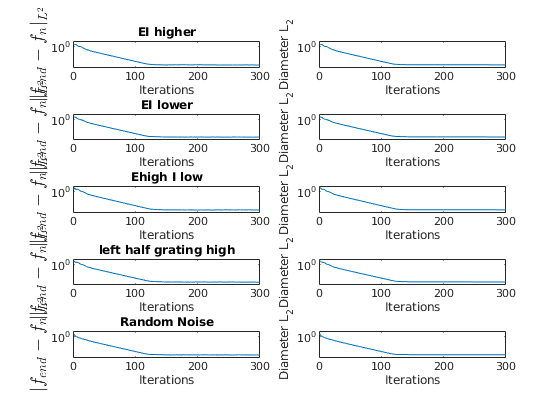

Elapsed time is 11.196453 seconds.


Elapsed time is 10.789572 seconds.


Elapsed time is 10.986032 seconds.


Elapsed time is 10.885671 seconds.


Elapsed time is 10.928457 seconds.


figure('Name','5 initial conditions')
for IniInd = 1:length(LDEIniAll)
    tic
    [LDEEpoOutAll{IniInd},L1DiffNormAll{IniInd},...
        L1DiffNormNeib{IniInd}, L2Diameter{IniInd},LDEequv(:,IniInd)] = ...
    LDEIteration_16FuncMain(...
    PixInptCtgrUse,LDEIniAll{IniInd},p,Epoc,...
    C_SS_mean,C_CS_mean,C_IS_mean,...
    C_SC_mean,C_CC_mean,C_IC_mean,...
    C_SI_mean,C_CI_mean,C_II_mean,...
    L4EmeshX,L4ImeshY,LDEFrfunc,...
    N_HCOut,NPixX,NPixY)  ;
    toc
    
    subplot(5,2,(IniInd-1)*2+1)
    plot(L1DiffNormAll{IniInd}/(N_HCOut^(2*(1/2))))
    set(gca, 'YScale', 'log')
    xlabel('Iterations');
    ylabel('$|f_{end} - f_n|_{L^2}$','interpreter','latex','FontSize',14)
    title(IniDespt{IniInd})
    ylim([1e-14 1e4])
    
    subplot(5,2,(IniInd)*2)
    plot(L2Diameter{IniInd}/(N_HCOut^(2*(1/2))))
    set(gca, 'YScale', 'log')
    xlabel('Iterations');
    ylabel('Diameter L_2')
    ylim([1e-14 1e4])
end


Comb = nchoosek(1:IniNum,2);
L1DiffAll = zeros(size(Comb,1),1);
for CInd = 1:size(Comb,1)
    Ind1 = Comb(CInd,1); Ind2 = Comb(CInd,2);
    L1DiffAll(CInd) = ...
        mean(abs(LDEEpoOutAll{Ind1}{end}.I-LDEEpoOutAll{Ind2}{end}.I),'all') + ...
        mean(abs(LDEEpoOutAll{Ind1}{end}.S-LDEEpoOutAll{Ind2}{end}.S),'all') + ...
        mean(abs(LDEEpoOutAll{Ind1}{end}.C-LDEEpoOutAll{Ind2}{end}.C),'all');
end

Check the 50-100 

EpcInvst = 35:300;
errAllTrails = zeros(NPixY*NPixX,IniNum*length(EpcInvst));
LDEIequvUse = mean(LDEequv,2);
InvstInd = 1;
for IniInd = 1:length(LDEIniAll)
    for EpcInd = EpcInvst
        err = LDEEpoOutAll{IniInd}{EpcInd}.I ...
            - LDEIequvUse(2*NPixY*NPixX*N_HCOut^2+1:end);
        errMap = reshape(err,N_HCOut*NPixY, N_HCOut*NPixX);
        err = reshape(errMap(1:NPixY,1:NPixX),NPixY*NPixX,1);
        err = err/norm(err);
        errAllTrails(:,InvstInd) = err;
        InvstInd = InvstInd+1;
    end    
end
[U,S,V] = svd(errAllTrails/sqrt(IniNum*length(EpcInvst)));
% U(:,1) is the primary 1D space??...

Present dynamics on the first 4 modes!

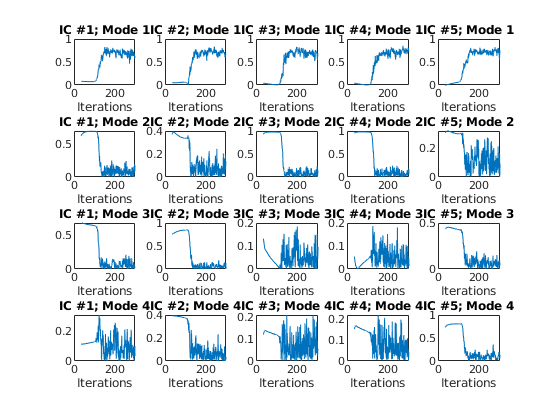

figure('Name','Mode Dynamics')
Win = length(EpcInvst);
for ModInd = 1:4
    AA = U(:,ModInd)'*errAllTrails;
    for ii = 1:length(LDEIniAll) 
        subplot(4,length(LDEIniAll),...
            ii + (ModInd-1)*length(LDEIniAll));
        plot(EpcInvst,abs(AA((ii-1)*Win+1:ii*Win))); 
        xlabel('Iterations')
        title(sprintf('IC #%d; Mode %d',ii,ModInd))
    end    
end

## 4.1 Test a large sample

NSample = NPixY*NPixX*3;
RadRange = 6:12;
for RadInd = RadRange
    Radius = 10^(-RadInd);
    %NoiseAll = normrnd(0,1,NPixY*NPixX*3,NSample)*Radius;
    %NoiseUse = [];
    
%     NoiNorm  = sqrt(sum(NoiseAll.^2,1));
%     NoiseAll = NoiseAll./repmat(NoiNorm,NPixY*NPixX*3,1)*Radius;
    % OutBound = (NoiNorm>1e-7) | (NoiNorm<1e-10);
    % NoiseAll(:,OutBound) = [];
    NoiseAll = diag(ones(NPixY*NPixX*3,1)) * Radius;
    LDEequv = LDEEpoOutAll{1}{end};
    
    LDEPertOutAll = cell(NSample,1);
    EpocTest = 10;
    L2Diff_OneStepAll = zeros(NSample,EpocTest+1);
    DiffVecAll = zeros(NSample,EpocTest+1,NPixY*NPixX*3);
    
    tic
    for TestInd = 1:NSample
        IniTest.S = symmHCs(LDEequv.S,N_HCOut,NPixX,NPixY,...
            NoiseAll(1:NPixY*NPixX,TestInd));
        IniTest.C = symmHCs(LDEequv.C,N_HCOut,NPixX,NPixY,...
            NoiseAll(NPixY*NPixX+1:2*NPixY*NPixX,TestInd));
        IniTest.I = symmHCs(LDEequv.I,N_HCOut,NPixX,NPixY,...
            NoiseAll(2*NPixY*NPixX+1:3*NPixY*NPixX,TestInd));
        
        [LDEPertOutAll{TestInd},~,~,~,~] = ...
            LDEIteration_16FuncMain(...
            PixInptCtgrUse,IniTest,p,EpocTest,...
            C_SS_mean,C_CS_mean,C_IS_mean,...
            C_SC_mean,C_CC_mean,C_IC_mean,...
            C_SI_mean,C_CI_mean,C_II_mean,...
            L4EmeshX,L4ImeshY,LDEFrfunc,...
            N_HCOut,NPixX,NPixY)  ;
        
        for EpcInd = 1:EpocTest+1
            LDEPertRslt = LDEPertOutAll{TestInd}{EpcInd};
            SDiff = LDEPertRslt.S - LDEequv.S;
            SDiffHC = reshape(SDiff,N_HCOut*NPixY,N_HCOut*NPixX);
            SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            CDiff = LDEPertRslt.C - LDEequv.C;
            CDiffHC = reshape(CDiff,N_HCOut*NPixY,N_HCOut*NPixX);
            CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            IDiff = LDEPertRslt.I - LDEequv.I;
            IDiffHC = reshape(IDiff,N_HCOut*NPixY,N_HCOut*NPixX);
            IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
            
            L2Diff_OneStepAll(TestInd,EpcInd) = ...
                sqrt(sum([SDiff;CDiff;IDiff].^2));
            DiffVecAll(TestInd,EpcInd,:) = [SDiff;CDiff;IDiff];
        end
    end
    toc
    save([SaveFolder sprintf('FewStepsIter_rad%d_Cub.mat',RadInd)],...
        'L2Diff_OneStepAll','DiffVecAll')
end

Elapsed time is 112.870172 seconds.
Elapsed time is 112.198654 seconds.
Elapsed time is 111.411211 seconds.
Elapsed time is 112.857561 seconds.
Elapsed time is 113.379313 seconds.
Elapsed time is 113.873056 seconds.
Elapsed time is 111.447495 seconds.


Fig

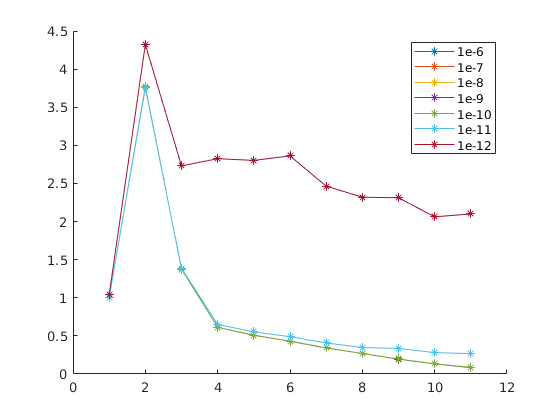

addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/LocalConv/'])
figure('Name','Diff test')
hold on
for RadInd = RadRange
    load([sprintf('FewStepsIter_rad%d.mat',RadInd)],...
        'L2Diff_OneStepAll','DiffVecAll')
    plot(0:EpocTest,median(L2Diff_OneStepAll,1)/10^(-RadInd),'-*',...
        'DisplayName',sprintf('1e-%d',RadInd))
    
end
xlabel('Iteration from Sphere'); 
ylabel('$$\left|\frac{x_n-x^*}{r_0}\right|$$','interpreter','latex')
legend

## 4.2 Do figure for Local perturbation test

load('ICTestWS.mat')
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/ICTest'])

h111 = figure('Name','DiffDistbs');
for RadiusInd = [11, 12, 12.5,13]
    NSample = 1e3;
    SaveTagNum = 9;
    EpocTest = 10;
    L2Diff_OneStepUse = zeros(SaveTagNum*NSample,EpocTest+1);
    DiffVecUse = zeros(SaveTagNum*NSample,EpocTest+1,NPixY*NPixX*3);
    
    for SaveID = 1:SaveTagNum
        load(sprintf('FewSteps_Rad%d_size%d_ID%d.mat',...
            RadiusInd,NSample,SaveID),'L2Diff_OneStepAll','DiffVecAll')
        
        L2Diff_OneStepUse((SaveID-1)*NSample+1:SaveID*NSample,:) ...
            = L2Diff_OneStepAll;
        DiffVecUse((SaveID-1)*NSample+1:SaveID*NSample,:,:) ...
            = DiffVecAll;
    end
    
    medIC = median(L2Diff_OneStepUse(:,1));
    medAll = zeros(6,1);
    for Epoc = 1:EpocTest+1
%         subplot(EpocTest+1,2,1+(Epoc-1)*2)
% %         x = L2Diff_OneStepAll(:,Epoc);
% %         [~,edges] = histcounts(log10(x));
% %         histogram(x,10.^edges)
%         histogram(L2Diff_OneStepAll(:,Epoc),100)
% %        set(gca, 'xscale','log')
% %        xlim([10^(-RadiusInd-2.5),10^(-RadiusInd+1)])
% %        xlim([])
%         xlabel('Distance to x^*')
%         title(sprintf('Iteration = %d',Epoc-1))
%         
%         subplot(EpocTest+1,2,2+(Epoc-1)*2)
%         DiffVecMat = squeeze(DiffVecAll(:,Epoc,:))';
%         NormNow = L2Diff_OneStepAll(:,Epoc)';
%         DiffVecMatNorm = DiffVecMat./repmat(NormNow,NPixY*NPixX*3,1);
%         [U1,S1,V1] = ...
%             svd(DiffVecMatNorm/sqrt(NSample));
%         plot(diag(S1),'-*')
%         xlabel('Modes'); ylabel('Singular Values')
%         xlim([1,20]); ylim([0 0.8])

        medAll(Epoc) = median(L2Diff_OneStepAll(:,Epoc)/1e-12);
    end
    hold on
    plot(0:EpocTest,medAll,'-*','DisplayName',sprintf('1e-%d',RadiusInd))
    
end
legend
%    saveas(h109,sprintf("%sSingularValues_1e4ICs_1e-%d_nmlz.fig",FigurePath,RadiusInd))

## 4.3 Global convergence

L2DiffAll_global = [];
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/'])
for Id1 = 1:4
    for Id2 = 1:4
        L2Diff = load(sprintf('GlobConv_IC%d_Ctrst%d.mat',Id1,Id2),'L2Diff_OneStepAll');
        L2Diff = L2Diff.L2Diff_OneStepAll;
        L2DiffAll_global = [L2DiffAll_global;L2Diff];
    end    
end

Epoc1e_0 = zeros(size(L2DiffAll_global,1),1);
Epoc1e_3 = zeros(size(L2DiffAll_global,1),1);
Epoc1e_9 = zeros(size(L2DiffAll_global,1),1);
figure
for TestId = 1:size(L2DiffAll_global,1)
    convCurve = L2DiffAll_global(TestId,:);
    Epoc1e_0(TestId) = length(find(convCurve>1));
    Epoc1e_3(TestId) = length(find(convCurve>1e-3));
    Epoc1e_9(TestId) = length(find(convCurve>1e-9));

    subplot(2,2,[1,3])
    hold on
    plot(convCurve,'Color',[0.8,0.8,0.8])
    
end
subplot(3,2,[1,3,5])
set(gca,'YScale','log')
xlim([0 201]); ylim([1e-13 1e4])
plot(21*ones(1,2),[1e-14 1e4],'r','LineWidth',2)
plot([0 201],1*ones(1,2),'b--')
plot([0 201],1e-3*ones(1,2),'b--')
plot([0 201],1e-9*ones(1,2),'b--')
xlabel('Iterations'); ylabel('|x(n) - x^*|')

subplot(3,2,2)
histogram(Epoc1e_0)
xlabel('Iteration # Reaching Unit Sphere')
xlim([15 120])
subplot(3,2,4)
histogram(Epoc1e_3)
xlim([15 120])
xlabel('Iteration # Reaching 10^{-3} Sphere')
subplot(3,2,6)
histogram(Epoc1e_9)
xlabel('Iteration # Reaching 10^{-9} Sphere')
xlim([15 120])